# SIR Model Team 3C - Reinfections 

Authors: Danny Burns, Joseph Gilbert, Diego Riverbay

Outcomes: 

- We will simulate the effects of recovered people becoming reinfected

- We will produce a model that can be used to demonstrate the effects of reinfections and potential public health measures implemented to reduce the number of reinfections

We will explain the causes and effects of a second wave of influenza.  This is interesting because it can show the real world effects of human attitudes and actions regarding the spread of the virus.  This would interest scientists, specifically epidemiologists and sociologists. 

## Question: 

Can recovered people becoming re-infectable (returned to the Susceptible category) explain why we often observe multiple waves of a disease? (Think about what it would take to convince a skeptical audience that your explanation is correct.)     

## Model 1: SIR Model With No Re-Infections

The first iteration of the model ignores re-infections.  This sets the baseline, allowing us to compare future models to a standard.

This represents a situation where people who have recovered no longer contribute to the model.  The model flows in one direction, which means that the virus eventually has no more susceptible hosts, and thus burns out.  This is evidenced by a single wave on a graph of infections, after which the virus decreases in prevalence until it is no longer detectable in the community.

Defining the Variables

𝛽 = This represents the infection rate.  People move from the susceptible stock to the infected stock according to this number, which is 1/89.8 in this model.

Ɣ = This represents the recovery rate.  People move from the infected stock to the recovered stock according to this number, which is ½ in this case.  

## Solving the model

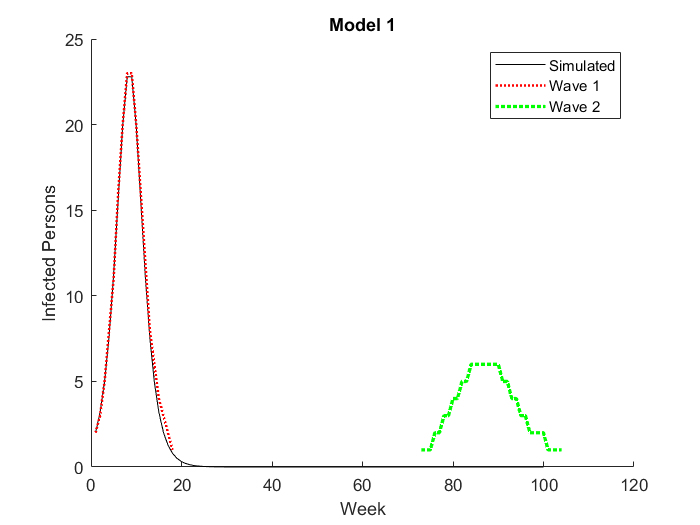


beta = 1 / 89.8; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
i_0 = 2;       % Initial count of infected persons

% Define initial state
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_long, I_long, R_long, W_long] = sir_simulate_v2(s_0, i_0, r_0, beta, gamma, 100);

% Plot the fitted simulation
figure(3); clf; hold on;

plot(W_long, I_long, 'k-'); label1 = "Simulated";
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 1.5); label2 = "Wave 1";
plot(tab_data_wave2.W, tab_data_wave2.I, 'g:', 'LineWidth', 2.0); label3 = "Wave 2";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2, label3})
title("Model 1")

## Results

With these configurations, we can manipulate beta to in order to match the prediction curve to the existing data for the first curve or the second curve, not both.  This indicates that the model is flawed.  The real world data includes a second wave, so being unable to model the second wave effectively invalidates the model for predicting longer term trends.  The model in its current form does not adequately allow public health officials and epidemiologists to understand what is likely to happen, so a new model is needed.  

## Model 2: SIR Model With Re-Infections

Model 1 is not really accurate in real world situations.  Immunity received from infection and recovery is usually short lived and not 100% effective even during the immune period, making Model 1 an incomplete representation.

In order to better understand the virus and its implications we needed a better model, specifically one that takes re-infections into account.  This project answers that call by adding an additional flow from recovered back to susceptible.  Adjusting the value of this flow (named Rho in our model) allows us to match the preliminary training data and account for future resurgences of the virus.  This model is better as it will allow scientists and public health professionals to have a better understanding of predicted viral behavior.  

## Defining the Variables

𝛽 = This represents the infection rate.  People move from the susceptible stock to the infected stock according to this number, which is 1/89 in this model.

Ɣ = This represents the recovery rate.  People move from the infected stock to the recovered stock according to this number, which is ½ in this case.  

⍴ = This represents the amount of people returning to the susceptible stock from the recovered stock.  We found that 1/60 reinfections best matches the training data.

## Solving the Model:

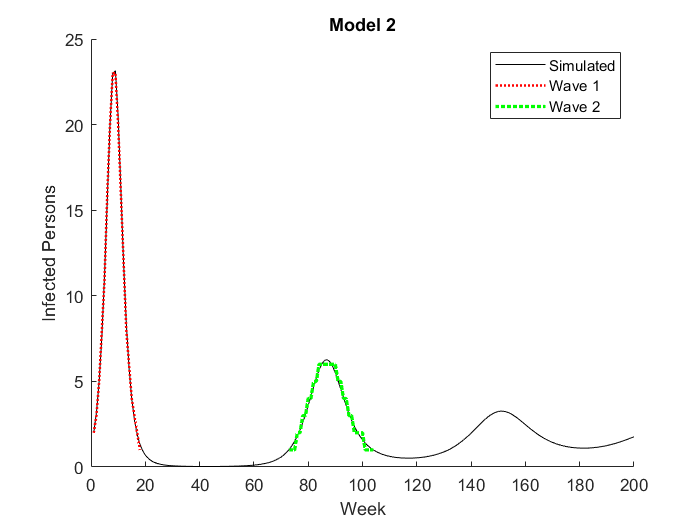

clear all
close all
clc

% Load the validation data
tab_data_validate = readtable("wave1.csv", "Delimiter", ",");
tab_data_wave2 = readtable("wave2.csv", "Delimiter", ",");

% Configure the simulation
beta = 1 /89.808; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / week)
rho = 1/60;  % reinfection rate 
i_0 = 2;       % Initial count of infected persons
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_long, I_long, R_long, W_long] = sir_simulate_v3(s_0, i_0, r_0, beta, gamma, rho, 200);

% Plot the fitted simulation
figure(3); clf; hold on;

plot(W_long, I_long, 'k-'); label1 = "Simulated";
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 1.5); label2 = "Wave 1";
plot(tab_data_wave2.W, tab_data_wave2.I, 'g:', 'LineWidth', 2.0); label3 = "Wave 2";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2, label3})
title("Model 2")


function [s_n, i_n, r_n] = sir_step_v3(s, i, r, beta, gamma, rho)
% fcn_step Advance an SIR model one timestep
%
% Usage
%   [s_n, i_n, r_n] = fcn_step(s, i, r, beta, gamma)
% 
% Arguments
%   s = current number of susceptible individuals
%   i = current number of infected individuals
%   r = current number of recovered individuals
%   
%   beta = infection rate parameter
%   gamma = recovery rate parameter
%   rho = reinfection rate parameter
% 
% Returns
%   s_n = next number of susceptible individuals
%   i_n = next number of infected individuals
%   r_n = next number of recovered individuals

% compute new infections and recoveries
infected = beta * i * s;
recovered = gamma * i;
resusceptible = rho *  r;
% Enforce invariants
total = s + i + r;
infected = min(s, infected);                % Cannot infect more people than current s
infected = min(total - i, infected);        % Cannot infect more than total
recovered = min(i, recovered);              % Cannot recover more people than current i
recovered = min(total - r, recovered);      % Cannot recover more than total
resusceptible= min(r, resusceptible);       % Cannot recover more people than current r
resusceptible= min(total-s, resusceptible); % Cannot recover more than total
% Update state
s_n = s + resusceptible - infected;
i_n = i + infected - recovered;
r_n = r + recovered - resusceptible;

% This way of enforcing invariants does not actually conserve persons!
%s_n = max(s_n, 0);
%i_n = max(i_n, 0);
%r_n = max(r_n, 0);
    
end

## Results:

By implementing an additional flow from recovered back to susceptible, we enabled our model to accurately simulate both the first and second wave of the virus.  We called this flow Rho, and determined that 1/60 best matches the training data. 

## Conclusion

Our model is now significantly more useful and accurate.  It matches the training data, allowing us to have a much better understanding of the timing and results of a second wave.  It also illuminates a general trend in multi wave viral outbreaks, namely that the waves will continue, albeit with decreasing severity.  Our model predicts this, although we do not have data to validate waves beyond the second.  